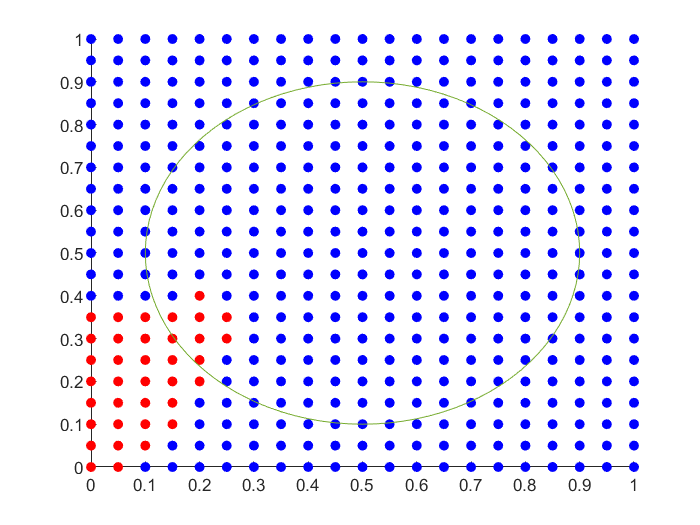

percentage_correct = 49.6599

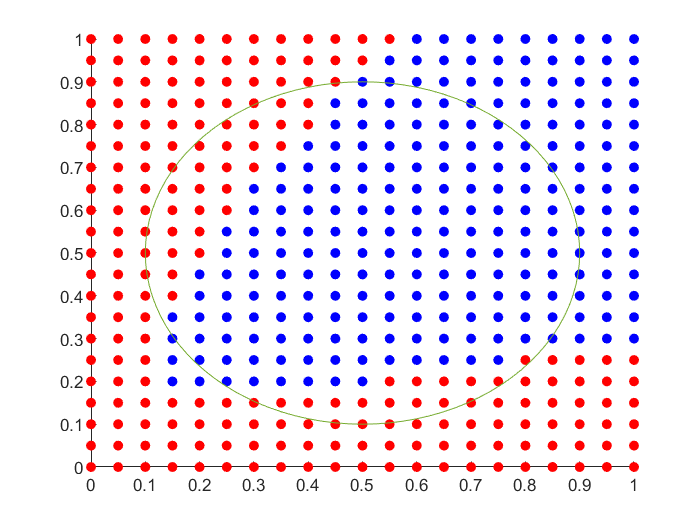

percentage_correct = 73.4694

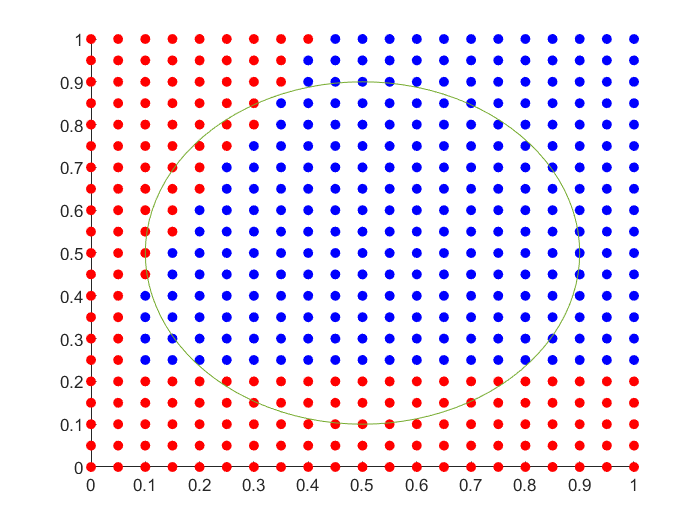

percentage_correct = 72.7891

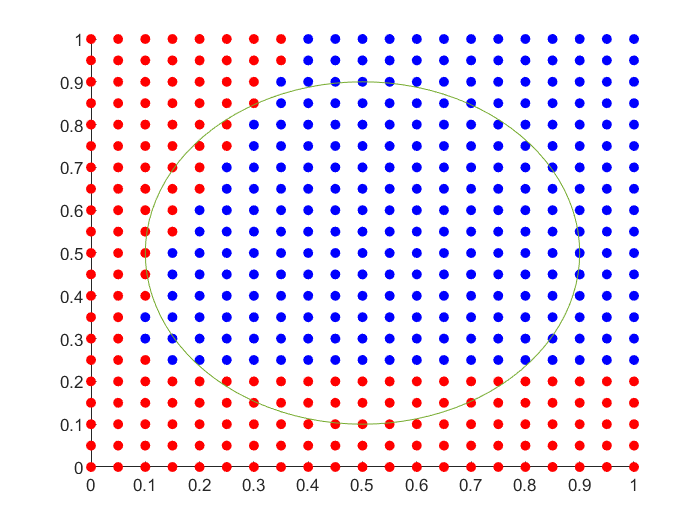

percentage_correct = 73.0159

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Cirkel");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    th = 0:pi/50:2*pi;
    xunit = 0.4 * cos(th) + 0.5;
    yunit = 0.4 * sin(th) + 0.5;
    
    figure(j)
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit, yunit);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))]

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35]

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    th = 0:pi/50:2*pi;
    xunit = 0.4 * cos(th) + 0.5;
    yunit = 0.4 * sin(th) + 0.5;
    
    figure(j)
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit, yunit);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))]

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35]

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    th = 0:pi/50:2*pi;
    xunit = 0.4 * cos(th) + 0.5;
    yunit = 0.4 * sin(th) + 0.5;
    
    figure(j)
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit, yunit);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end